get paths, clear workspace

filePath = matlab.desktop.editor.getActiveFilename;
cd(filePath(1:strfind(filePath,'livescripts/cell_mig')-1))
addpath(genpath(filePath(1:strfind(filePath,'livescripts/cell_mig')-1)));
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')

load for mean-field discovery

dr = '/home/danielmessenger/Dropbox/Boulder/research/data/wound_healing/'; % rate data 1-5, 1 being the best
% load([dr,'20240530/r02c09f07.mat']) % 2.5
% load([dr,'20240604/r02c09f07_ROI2.mat']) % 3
% load([dr,'20240604/r02c09f08_ROI1.mat']) % 2
% load([dr,'20240604/r02c09f08_ROI2.mat']) % 3
load([dr,'20240604/r02c09f09_ROI1.mat']) %1.5
% load([dr,'20240604/r02c09f09_ROI2.mat']) % 2
% load([dr,'20240604/r03c11f05_ROI1.mat']) % 1.5
% load([dr,'20240604/r03c11f05_ROI2.mat']) % 2
% load([dr,'20240604/r03c11f06_ROI1.mat']) % 2
% load([dr,'20240604/r03c11f06_ROI2.mat']) % 3

N = tracks.NumTracks;
M = tracks.MaxFrame;
X = zeros(N,2,M)+NaN;
clf
for n=1:N
    X(n,:,tracks.Tracks(n).Frames) = cell2mat(tracks.Tracks(n).Data.Centroid')';
    % X(n,1,:) = fillmissing(X(n,1,:),'linear','EndValues','none');
    % X(n,2,:) = fillmissing(X(n,2,:),'linear','EndValues','none');
end
t = 0:8/60:(M-1)*8/60;
Xscell = {X};

Compute approximate particle distribution $U$ from particles *Xscell* 

exps = 1; %choose experiments from Xscell to use in regression (if Xscell contains multiple exps)
NN = N; %choose number of particles to use from each experiment
numx = 48 + 1; %choose histogram grid resolution
numsdv = inf;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0.05 1 1]];
scoord = 0;
Xsnz = [0 1]; %set extrinsic noise level
norml = 'count';

get_particle_distrib; %compute histogram

ET_load_data = 0.5668 


View histogram data

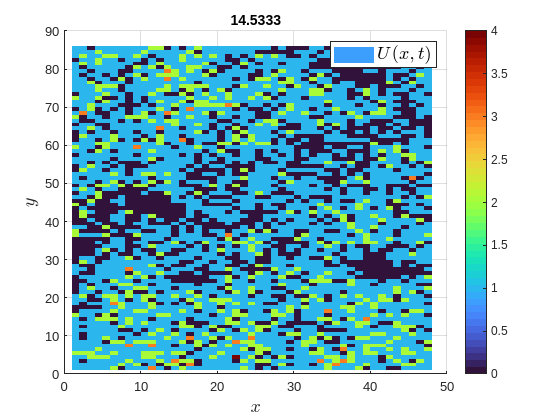

plotgap=1;
plot_distrib;

Choose model library

% local autonomous operators
max_dx = [0 2];
max_dt = 0;
polys = 1:2;
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {};%@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

% local non-autonomous operators
driftpolys=[0:2]; drifttrigs=[];
diffpolys=[0]; difftrigs=[]; crossdrift=0;

% non-local operators
dx = mean(diff(xs_obs{1}));
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[],'Sing',[],'Exp',[1./(2*dx:4*dx:20*dx)],'Singeps',[0.01],'svdtol',[1e-4]}};
% convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[0:3],'Sing',[0],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 0.0208 


Set weak discretization

phi_class = {1,1};
sm_x = 4; % set ratio of query-point gap to test function radius in spatial dims
sm_t = 4; % set ratio of query-point gap to test function radius in time 

% manually set test function params
p_x = 3; mxs = floor(length(xs_obs{1})/4);
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 24;
tau_t = []; k_t = []; tauhat_t = [];

% set test function params using cornerpoint
% tauhat_x = 2; tau_x = 10^-8;
% p_x = []; mxs = 1;
% tauhat_t = 2; tau_t = 10^-8;
% p_t = []; mts = 1;

% rescale coordinates
scales = 2;

% use approx. variance for improved conditioning
covtol = 0;

% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-2;

set_discretization;

ET_setdisc = 0.3090 


View average FFT info

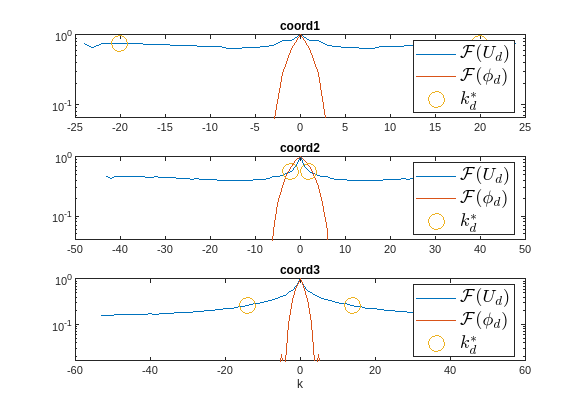

toggle_plot_fft = 1;
plot_Ufft;

Build linear systems

build_Gb;

ET_build_Gb = 1.0903 


MSTLSQP

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 1/(0.01*size(G,2)+1);
maxits = Inf;
sparsity_scale = 1;
excl_tags= {'([x.^0.*y.^0.*t.^0]u^1)_{lap}','u^{2}_{}'};
excl_tols = [0.01 -0.001];
excl_signs = [-1 1];
% excl_tags= {'([x.^0.*y.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{yy}','u^{2}_{}'};
% excl_tols = [0.01 0.01 -0.001];
% excl_signs = [-1 -1 1];
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

%% solve sparse regression problem
tic;
gamma = (cond(G)>gamma_tol)*min(10.^(-(16+min(log10(lambda)))/2),0.1/norm(G));
if exist('excl_tags','var')
    excl_inds={ismember(tags_pde_G,excl_tags)};
else
    excl_inds={};
end
if ~all(cellfun(@(x)all(x==0),excl_inds))
    iinds = find(excl_inds{1});
    Aineq = zeros(length(iinds),length(excl_inds{1}));
    bineq = zeros(length(iinds),1);
    for j=1:length(excl_tags)
        Aineq(j,ismember(tags_pde_G,excl_tags{j})) = excl_signs(j);
        bineq(j) = excl_signs(j)*excl_tols(j);
        if ~isempty(M)
            bineq(j)=bineq(j)/M(ismember(tags_pde_G,excl_tags{j}),:); 
        end
    end
    Aineq = {Aineq};
    bineq = {bineq};
else
    Aineq=repmat({[]},size(b,2));
    bineq=repmat({[]},size(b,2));
    excl_inds=repmat({[]},size(b,2));
end
vars = {'meth',meth,'keeprows',inds_keep,'cov',cov,'lambda',lambda,'gamma',gamma,...
    'M',M,'maxits',maxits,'sparsity_scale',sparsity_scale,'alpha',alpha,'excl_inds',excl_inds,...
    'Aineq',Aineq,'bineq',bineq,'tol',tol};
[W,resid,its_all,lossvals,thrs_EL,lambda_hat,G_fin,b_fin] = solve_sparsereg(G,b,vars{:});
ET_solve_sparse_reg = toc;
fprintf(1,'ET_solve_sparse_reg = %4.4f \n',ET_solve_sparse_reg);

ET_solve_sparse_reg = 0.6072 


get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = -0.001u^{2}_{} + -24.3013([x.^0.*y.^0.*t.^0]u^1)_{x} + 0.114757([x.^1.*y.^0.*t.^0]u^1)_{x} + -27.3561([x.^0.*y.^0.*t.^0]u^1)_{y} + 0.0147353([x.^1.*y.^0.*t.^0]u^1)_{y} + 0.0540863([x.^0.*y.^1.*t.^0]u^1)_{y} + 550.931([x.^0.*y.^0.*t.^0]u^1)_{lap} + -0.651313conve0.040201 + 0.393282conve0.0134 + -0.416659conve0.0080402 + 0.257419conve0.0044668
Relative Res: ||b-G*W||_2/||b||_2 = 6.00e-01TP Score = NaN
      
polys = 1 2 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 12 24 
[s_x s_t] = 3 6 
[p_x p_t] = 3 3 
 scales = 1.56e+00 1.64e-02 1.64e-02 3.12e-01 
      
Total particles = 11055 
Size of dataset = 48 86 105 
Size G = 1680 20 
Cond G = 6.98e+10
[lambda_hat gamma] = 1.048e-02 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 2 
 
ET_load_data = 0.1554 
ET_build_lib = 0.0208 
ET_setdisc = 0.3090 
ET_build_Gb = 1.0903 
ET_solve_sparse_reg = 0.6072 
Elapsed time WSINDy = 2.1827 


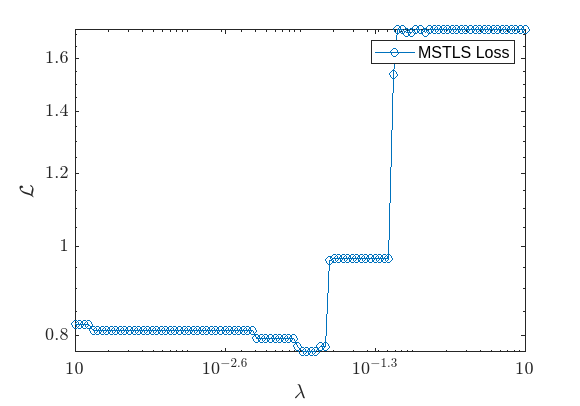

% Display loss
toggle_plot_loss = 1;
plot_loss;

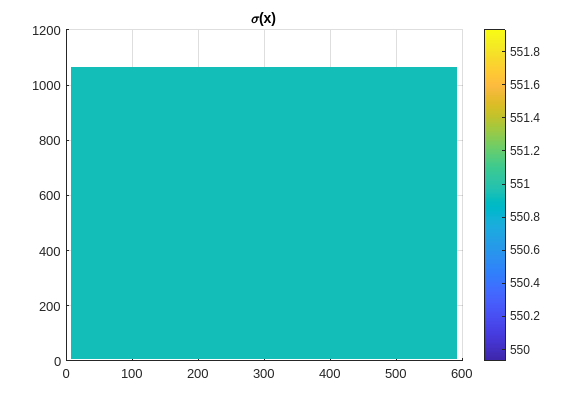

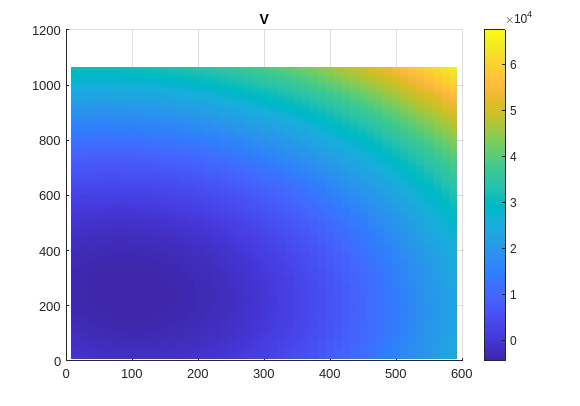

% Display drift/diffusion
toggle_plot_drift = 1;
plot_driftdiff;

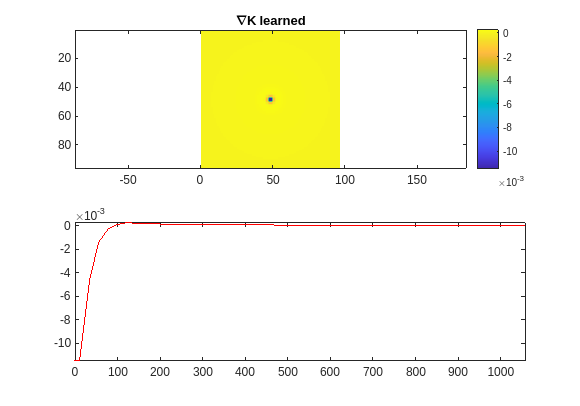


% Display interaction force
toggle_plot_IPforce = 1;
plot_K